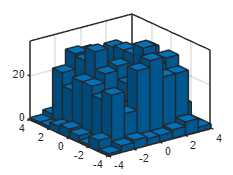

data = dlmread('map_0.log');
n = 1000;
X = rand(2,n)*2*pi-pi;
colpicked = randsample(1:40000,n);
Y = [data(4,colpicked);data(5,colpicked)]; 
histogram2(X(1,:),X(2,:));

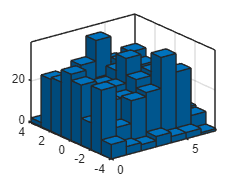

histogram2(Y(1,:),X(2,:));

C = zeros(n,n);
for i = 1:n
    for j = 1:n
        C(i,j) = norm(Y(:,i)-X(:,j))^2;
    end
end
r = ones(n,1)/n;
c = ones(n,1)/n;
X0 = r*c';

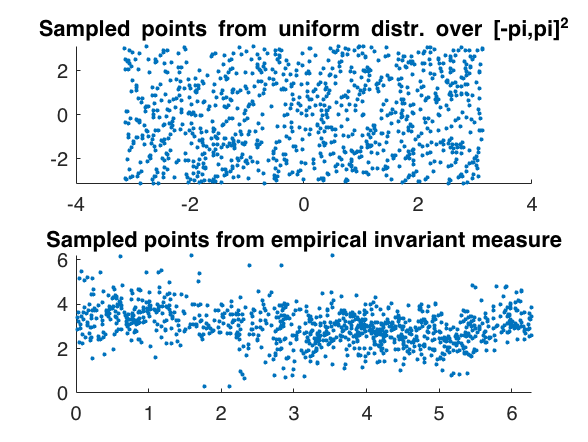

figure
subplot(2,1,1);
scatter(X(1,:),X(2,:),'.');
title('Sampled points from uniform distr. over [-pi,pi]^2')
subplot(2,1,2);
scatter(Y(1,:),Y(2,:),'.');
title('Sampled points from empirical invariant measure')

## Optimal solution

f = reshape(C,[n^2,1]);
x_vec = reshape(X0,[n^2,1]);
A = zeros(2*n,n^2);
for i = 1:n
    A(1:n,(i-1)*n+1:i*n) = speye(n);
    A(n+i,(i-1)*n+1:i*n) = ones(1,n);
end
A = sparse(A);
lb = -x_vec;
tic
options = optimoptions('linprog','Algorithm','dual-simplex','ConstraintTolerance',1e-9,'OptimalityTolerance',1e-10);
[d,val,exitflag,output] = linprog(f,[],[],A,zeros(2*n,1),lb,[],options);

Optimal solution found.



time_global = toc;
x_vec = x_vec + d;
x_opt = x_vec;
X_opt = reshape(x_vec, [n,n]);
f_opt = trace(C'*X_opt);

## Vanilla Random Block Coordinate Descent

[fval_rbcd,time_rbcd,feas_rbcd,card_rbcd,X1]=RBCD0(r,c,n,X0,f_opt,C,10000,5000,0);

iter = 1000, accuracy = 0.62298
iter = 2000, accuracy = 0.47649
iter = 3000, accuracy = 0.41699
iter = 4000, accuracy = 0.38659
iter = 5000, accuracy = 0.38214
number of successful iterations =4059


## RBCD-Diagonal Band

[fval_rbcddb,time_rbcddb,feas_rbcddb,X1,card_rbcddb] = reRBCD(r,c,n,X0,f_opt,C,100,5000,1,0); 

iter = 1000, accuracy = 0.60013
iter = 2000, accuracy = 0.39083
iter = 3000, accuracy = 0.30828
iter = 4000, accuracy = 0.26167
iter = 5000, accuracy = 0.22939
number of successful iterations =5000


## RBCD-Submatrix and Diagonal Band

[fval_rbcdsdb,time_rbcdsdb,feas_rbcdsdb,X1,card_rbcdsdb] = reRBCD(r,c,n,X0,f_opt,C,100,5000,0.1,0);

iter = 1000, accuracy = 0.041847
iter = 2000, accuracy = 0.021645
iter = 3000, accuracy = 0.015266
iter = 4000, accuracy = 0.011895
iter = 5000, accuracy = 0.0097821
number of successful iterations =5000


## Accelerated RBCD

[fval_arbcd,time_arbcd,feas_arbcd,X1,card_arbcd] = ARBCD(r,c,n,X0,f_opt,C,100,5000,0);

iter = 1000, accuracy = 0.016883
iter = 2000, accuracy = 0.011769
iter = 3000, accuracy = 0.0094083
iter = 4000, accuracy = 0.0080815
iter = 5000, accuracy = 0.0070273
number of successful iterations =5000


## Plot

figure
semilogy(time_rbcd,fval_rbcd,'-o','MarkerIndices',1:5:length(fval_rbcd),'LineWidth',2)
hold on
semilogy(time_rbcddb,fval_rbcddb,'-+','MarkerIndices',1:5:length(fval_rbcddb),'LineWidth',2)
hold on
semilogy(time_rbcdsdb,fval_rbcdsdb,'-x','MarkerIndices',1:5:length(fval_rbcdsdb),'LineWidth',2)
hold on
semilogy(time_arbcd,fval_arbcd,'-v','MarkerIndices',1:5:length(fval_arbcd),'LineWidth',2)
legend('RBCD','RBCD-DB','RBCD-SDB','ARBCD')
title('2-d case')
xlabel('time (s)')
ylabel('fk - f*')
set(gca,'FontSize',18)

figure
semilogy(time_rbcd,feas_rbcd,'-o','MarkerIndices',1:5:length(fval_rbcd),'LineWidth',2)
hold on
semilogy(time_rbcddb,feas_rbcddb,'-+','MarkerIndices',1:5:length(fval_rbcddb),'LineWidth',2)
hold on
semilogy(time_rbcdsdb,feas_rbcdsdb,'-x','MarkerIndices',1:5:length(fval_rbcdsdb),'LineWidth',2)
hold on
semilogy(time_arbcd,feas_arbcd,'-v','MarkerIndices',1:5:length(fval_arbcd),'LineWidth',2)
legend('RBCD','RBCD-DB','RBCD-SDB','ARBCD')
title('2-d case')
xlabel('time (s)')
ylabel('feas. err.')
set(gca,'FontSize',18)

figure
semilogy(card_rbcd,'-o','MarkerIndices',1:500:length(card_rbcd),'LineWidth',2)
hold on
semilogy(card_rbcddb,'-+','MarkerIndices',1:500:length(card_rbcddb),'LineWidth',2)
hold on
semilogy(card_rbcdsdb,'-x','MarkerIndices',1:500:length(card_rbcdsdb),'LineWidth',2)
hold on
semilogy(card_arbcd,'-v','MarkerIndices',1:500:length(card_arbcd),'LineWidth',2)
legend('RBCD','RBCD-DB','RBCD-SDB','ARBCD')
title('2-d case')
xlabel('Iteration')
ylabel('# of nonzeros in xk')
set(gca,'FontSize',18)